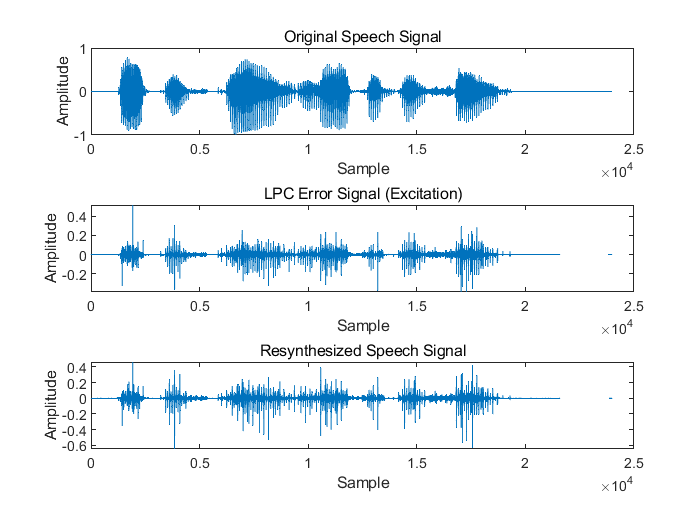

% Load speech signal
[speech,fs] = audioread('s5.wav');

% Define frame length and overlap
frame_length = 0.04; % 40 ms
overlap = 0.75; % 75%

% Convert frame length and overlap to samples
frame_length_samples = round(frame_length*fs);
overlap_samples = round(overlap*frame_length_samples);

% Define LPC order
p = 128;

% Initialize variables for resynthesized speech signal
resynthesized = zeros(length(speech),1);
excitation = zeros(length(speech),1);

% Loop through frames of speech signal
for n = 1:overlap_samples:length(speech)-frame_length_samples+1
    
    % Extract frame of speech
    speech_frame = speech(n:n+frame_length_samples-1);
    
    % Perform LPC analysis on frame
    [a,g] = lpc(speech_frame,p);
    
    % Generate LPC error signal
    lpc_error = filter(a,1,speech_frame);
    
    % Save LPC error signal to appropriate location in resynthesized signal
    resynthesized(n:n+frame_length_samples-1) = resynthesized(n:n+frame_length_samples-1) + lpc_error;
    
    % Generate excitation signal from LPC error signal
    excitation(n:n+frame_length_samples-1) = lpc_error;
    
end

% Plot original speech signal, error signal, and resynthesized speech signal
figure;
subplot(3,1,1);
plot(speech);
title('Original Speech Signal');
xlabel('Sample');
ylabel('Amplitude');
subplot(3,1,2);
plot(excitation);
title('LPC Error Signal (Excitation)');
xlabel('Sample');
ylabel('Amplitude');
subplot(3,1,3);
plot(resynthesized);
title('Resynthesized Speech Signal');
xlabel('Sample');
ylabel('Amplitude');